# Notations and data

NOTES TO USERS:

- notebooks are by nature sequential. Chunks at the end depend on variables defined in the snippets at the beginning: don’t forget to proceed in order!

- only the code is provided. For comments of methods & results, we refer to the book.

- please report errors!

**Step 0**: please make sure the dataset is in your working directory!

data_ml = readtable('data_ml.csv') ;
data_ml = removevars( data_ml, "Var1" ) ;
head(data_ml)

ans = 8×99 table
    stock_id       date       Advt_12M_Usd    Advt_3M_Usd    Advt_6M_Usd    Asset_Turnover    Bb_Yld     Bv     Capex_Ps_Cf    Capex_Sales    Cash_Div_Cf    Cash_Per_Share    Cf_Sales    Debtequity    Div_Yld    Dps     Ebit_Bv    Ebit_Noa    Ebit_Oa    Ebit_Ta    Ebitda_Margin    Eps     Eps_Basic    Eps_Basic_Gr    Eps_Contin_Oper    Eps_Dil     Ev     Ev_Ebitda    Fa_Ci    Fcf     Fcf_Bv    Fcf_Ce    Fcf_Margin    <

data_ml = data_ml( data_ml.date > datetime(1999,12,31) & ...
                   data_ml.date < datetime(2019,01,01) , : ) ;
data_ml = sortrows(data_ml,["stock_id","date"]) ;
head(data_ml(1:6,1:6))

ans = 6×6 table
    stock_id       date       Advt_12M_Usd    Advt_3M_Usd    Advt_6M_Usd    Asset_Turnover
    ________    __________    ____________    ___________    ___________    ______________

       1        2000-01-31        0.41           0.39           0.42             0.19     
       1        2000-02-29        0.41           0.39            0.4             0.19     
       1        2000-03-31         0.4           0.37           0.37              0.2     
       1        2000-04-30        0.39           0.36           0.37              0.2     
       1        2000-05-31         0.4           0.42            0.4              0.2     
       1        2000-06-30        0.41           0.47           0.42             0.21     


Then, a first graph to check data availability through time.

data_summary = groupcounts(data_ml(:, ["date","stock_id"]), "date") ;
data_summary.Properties.VariableNames = {'date','nb_assets'} ;
head(data_summary)

ans = 8×2 table
       date       nb_assets
    __________    _________

    2000-01-31      1054   
    2000-02-29      1054   
    2000-03-31      1088   
    2000-04-30      1088   
    2000-05-31      1088   
    2000-06-30      1097   
    2000-07-31      1097   
    2000-08-31      1096   


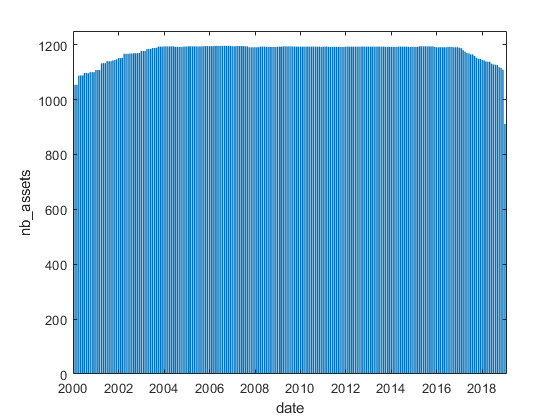

bar(data_summary.date, data_summary.nb_assets)
ylim([0 1250])
xlabel('date')
ylabel('nb\_assets')

There are four immediate **labels** in the dataset: R1M_Usd, R3M_Usd, R6M_Usd and R12M_Usd, which correspond to the 1 month, 3 month, 6 month and 12 month future/forward returns of the stocks. The returns are **total returns**, that is, they incorporate potential **dividend** payments over the considered periods. This is a better proxy of financial gain compared to price returns only. We refer to the analysis of @hartzmark2019dividendfor a study on the impact of decoupling price returns and dividends. These labels are located in the last 4 columns of the dataset. We provide their descriptive statistics below.

cols_summarize = ["R1M_Usd","R3M_Usd","R6M_Usd","R12M_Usd"] ;

meanData = rows2vars( varfun( @mean, data_ml(:, cols_summarize ) ) ) ;
stdData =  rows2vars( varfun( @std,  data_ml(:, cols_summarize ) ) ) ;
minData =  rows2vars( varfun( @min,  data_ml(:, cols_summarize ) ) ) ;
maxData =  rows2vars( varfun( @max,  data_ml(:, cols_summarize ) ) ) ;

all_stats =  array2table( horzcat( meanData{:,2}, stdData{:,2}, minData{:,2}, maxData{:,2} ), ...
    "VariableNames",["mean","std","min","max"], ...
    "RowNames", cols_summarize ) ;
head( all_stats )

ans = 4×4 table
                  mean        std       min       max  
                ________    _______    ______    ______

    R1M_Usd     0.012732    0.17643    -0.922    30.176
    R3M_Usd     0.036901    0.32829    -0.929    39.389
    R6M_Usd     0.072339    0.52742     -0.98    106.93
    R12M_Usd     0.13686    0.73787    -0.991    95.972


In anticipation for future models, we keep the name of the predictors in memory. In addition, we also keep a much shorter list of predictors.

features = data_ml.Properties.VariableNames(3:95) ;
features_short = [ "Div_Yld", "Eps", "Mkt_Cap_12M_Usd", ...
                   "Mom_11M_Usd", "Ocf", "Pb", "Vol1Y_Usd" ] ;

The predictors have been uniformized, that is: for any given feature and time point, the distribution is uniform. Given 1,207 stocks, the graph below cannot display a perfect rectangle.

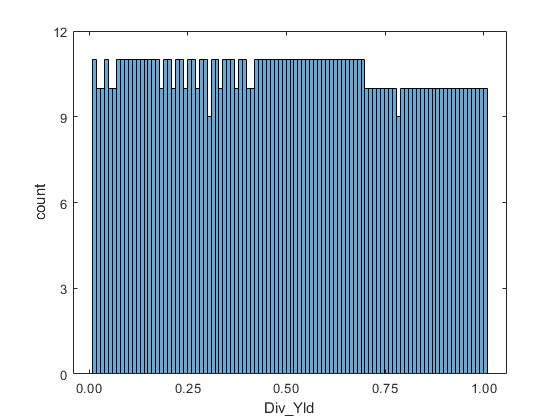

histogram( data_ml{ data_ml.date == datetime(2000,02,29), "Div_Yld" }, 100 )
xlabel('Div\_Yld')
ylabel('count')
yticks(0:3:12)
xticks(0.00:0.25:1.00)
xtickformat('%0.2f')

In order to be able to perform classification analyses, we create additional labels that are categorical.

data_ml.R1M_Usd_C = false( height(data_ml), 1 ) ;
data_ml.R12M_Usd_C = false( height(data_ml), 1 ) ;

data_ml.R1M_Usd_C  = data_ml.R1M_Usd  > median(data_ml.R1M_Usd) ;
data_ml.R12M_Usd_C = data_ml.R12M_Usd > median(data_ml.R12M_Usd) ;

The new labels are binary: they are equal to 1 (true) if the original return is above that of the median return over the considered period and to 0 (false) if not. Hence, at each point in time, half of the sample equal to zero and the other half to one: some stocks overperforms and others underperform.

In machine learning, models are estimated on one portion of data (**training set**) and then tested on another portion of the data (**testing set**) to assess their quality. We split our sample accordingly.

separation_date = datetime( 2014, 01, 15 ) ;
training_sample = data_ml( data_ml.date <  separation_date, : ) ;
testing_sample =  data_ml( data_ml.date >= separation_date, : ) ;

We also keep in memory a few key variables, like the list of asset identifiers and a rectangular version of returns. For simplicity, in the computation of the latter, we shrink the investment universe to keep only the stocks for which we have the maximum number of points.

stock_ids = data_ml.stock_id ;
stock_days = groupcounts( data_ml(:,["stock_id","date"]), "stock_id" ) ;
stock_days.Properties.VariableNames{2} = 'nb' ;
head(stock_days)

ans = 8×2 table
    stock_id    nb 
    ________    ___

       1        228
       2        225
       3        228
       4        228
       5        227
       6        227
       7        228
       8        227


stock_ids_short = stock_days(stock_days.nb == max(stock_days.nb) , "stock_id" ) ;

for stock_count = 1 : height(stock_ids_short)

    current_stock = stock_ids_short{stock_count,:} ;
    
    if stock_count == 1

        returns = data_ml( data_ml.stock_id == current_stock, ["date","R1M_Usd"] ) ;
        returns.Properties.VariableNames{stock_count + 1 } = num2str( current_stock ) ;
        
    else
        
        temp_returns = data_ml( data_ml.stock_id == current_stock, ["date","R1M_Usd"] ) ;
        temp_returns.Properties.VariableNames{2} = num2str( current_stock ) ;
        returns = outerjoin(returns, temp_returns, "keys", "date", "Type","Right","MergeKeys",true) ;
        
    end
    
    
end

head(returns)

ans = 8×794 table
       date         1         3         4         7         9         11        12        16        17        18        20        21        22        24        26        27        30        31        32        33        34        36        39        40        41        42        44        45        46        47        48        52        53        54        55        